modelName = 'TA2445';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','1')
set_param(modelName + "/Manual Switch2",'sw','1')

p = sdo.getParameterFromModel(modelName,'IPTGconc');

p.Value = 0.01;
p.Minimum = 0.01;
p.Maximum = 1;
p.Scale = 0.0001;
p.Free = 1;

options = sdo.OptimizeOptions;
options.Method = 'fmincon';

Exp = sdo.Experiment(modelName);
Exp = setEstimatedValues(Exp,p);

IPASignal = Simulink.SimulationData.Signal;
IPASignal.Name = 'IPA';
IPASignal.BlockPath = modelName + "/Demux";
IPASignal.PortType = 'outport';
IPASignal.PortIndex = 5;
IPASignal.Values = timeseries((1:51)',(1:51.5)+0.5');

Exp.OutputData = IPASignal; % add the signal object to the experiment

Simulator = createSimulator(Exp);
estFcn = @(p) optInputObjective(p,Simulator,Exp);

val = optInputObjective(p,Simulator,Exp);
val.F

ans = -29.3760

tic
[optInput,optInputInfo] = sdo.optimize(estFcn,p,options)


 最適化開始時間 11-Mar-2023 14:20:34

                               max                     First-order 
 Iter F-count        f(x)   constraint    Step-size    optimality
    0      2      -29.376            0
    1      4     -29.5406            0        0.397        0.395
    2      6     -30.3458            0         1.98        0.389
    3      9     -33.9464            0         9.72        0.342
    4     12     -44.3966            0         42.8         0.17
    5     15     -49.7428            0         42.5       0.0919
    6     18      -53.065            0         49.7       0.0478
    7     21     -54.9067            0         53.8       0.0238
    8     24     -55.7891            0         53.4       0.0108
    9     27     -56.1021            0         44.1      0.00412
   10     30     -56.1699            0         27.4      0.00116
   11     33      -56.176            0         10.7      0.00018
制約を満たす局所的最小値が見つかりました。

目的関数が最適性の許容誤差値の範囲内の実行可能な方向
において非減少であり、制約が制約の許容誤差値の範囲内で
満た

optInputInfo = フィールドをもつ struct :
               F: -56.1760
       Gradients: [1×1 struct]
        exitflag: 1
      iterations: 11
    SolverOutput: [1×1 struct]
           Stats: [1×1 struct]


toc

経過時間は 25.767227 秒です。


maxIPA_TA2445 = -optInputInfo.SolverOutput.fval;

SetPointValues = logspace(-2,1,100);
spv_length = length(SetPointValues);
for i = 1:1:spv_length
    in(i) = Simulink.SimulationInput(modelName);
    in(i) = in(i).setBlockParameter(modelName + "/To optimize input",...
        'Value',num2str(SetPointValues(i)));
end

out_TA2445 = sim(in,'ShowSimulationManager','on','ShowProgress','on')

[11-Mar-2023 14:21:03] シミュレーションの実行中...
[11-Mar-2023 14:21:04] シミュレーション実行 1/100 が完了
[11-Mar-2023 14:21:05] シミュレーション実行 2/100 が完了
[11-Mar-2023 14:21:06] シミュレーション実行 3/100 が完了
[11-Mar-2023 14:21:06] シミュレーション実行 4/100 が完了
[11-Mar-2023 14:21:07] シミュレーション実行 5/100 が完了
[11-Mar-2023 14:21:08] シミュレーション実行 6/100 が完了
[11-Mar-2023 14:21:09] シミュレーション実行 7/100 が完了
[11-Mar-2023 14:21:10] シミュレーション実行 8/100 が完了
[11-Mar-2023 14:21:10] シミュレーション実行 9/100 が完了
[11-Mar-2023 14:21:11] シミュレーション実行 10/100 が完了
[11-Mar-2023 14:21:12] シミュレーション実行 11/100 が完了
[11-Mar-2023 14:21:12] シミュレーション実行 12/100 が完了
[11-Mar-2023 14:21:13] シミュレーション実行 13/100 が完了
[11-Mar-2023 14:21:14] シミュレーション実行 14/100 が完了
[11-Mar-2023 14:21:15] シミュレーション実行 15/100 が完了
[11-Mar-2023 14:21:15] シミュレーション実行 16/100 が完了
[11-Mar-2023 14:21:16] シミュレーション実行 17/100 が完了
[11-Mar-2023 14:21:17] シミュレーション実行 18/100 が完了
[11-Mar-2023 14:21:18] シミュレーション実行 19/100 が完了
[11-Mar-2023 14:21:18] シミュレーション実行 20/100 が完了
[11-Mar-2023 14:21:19] シミュレーション実行 21/100 が完了
[11-Mar-2023 14:21:20] シミ

out_TA2445 = 1x100 Simulink.SimulationOutput 配列



Bfinal = zeros(spv_length,2);
Bfinal(:,1) = SetPointValues;
for i = 1:1:spv_length
    Bfinal(i,2) = out_TA2445(i).yout{1}.Values.Data(end);
end

IPAfinal = zeros(15,2);
IPAfinal(:,1) = [0.01 0.03 0.05 0.1 1 ...
                0.01 0.03 0.05 0.1 1 ...
                0.01 0.03 0.05 0.1 1]';
for expIdx = 1:15
    a = readtable("TA2445Data.xlsx","Sheet",expIdx);
    IPAfinal(expIdx,2) = a.IPA(end);
end

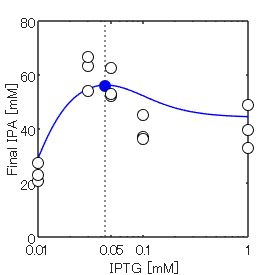

figure('Position', [100 100 200 200]);
plot(Bfinal(:,1),Bfinal(:,2),'b-')
xline(optInput.Value,':')
xlim([0.01 1])
ylim([0 80])
xlabel('IPTG [mM]')
xticks([0.01 0.05 0.1 1])
yticks([0 20 40 60 80])
ylabel('Final IPA [mM]')
hold on
plot(optInput.Value,maxIPA_TA2445,'bo','MarkerFaceColor','b')
plot(IPAfinal(:,1),IPAfinal(:,2),'ko','MarkerFaceColor','w')
hold off
set(gca,'xscale','log')

sdo.setValueInModel(modelName,optInput);